# MATLAB® による宇宙のデータを用いたデータ解析入門

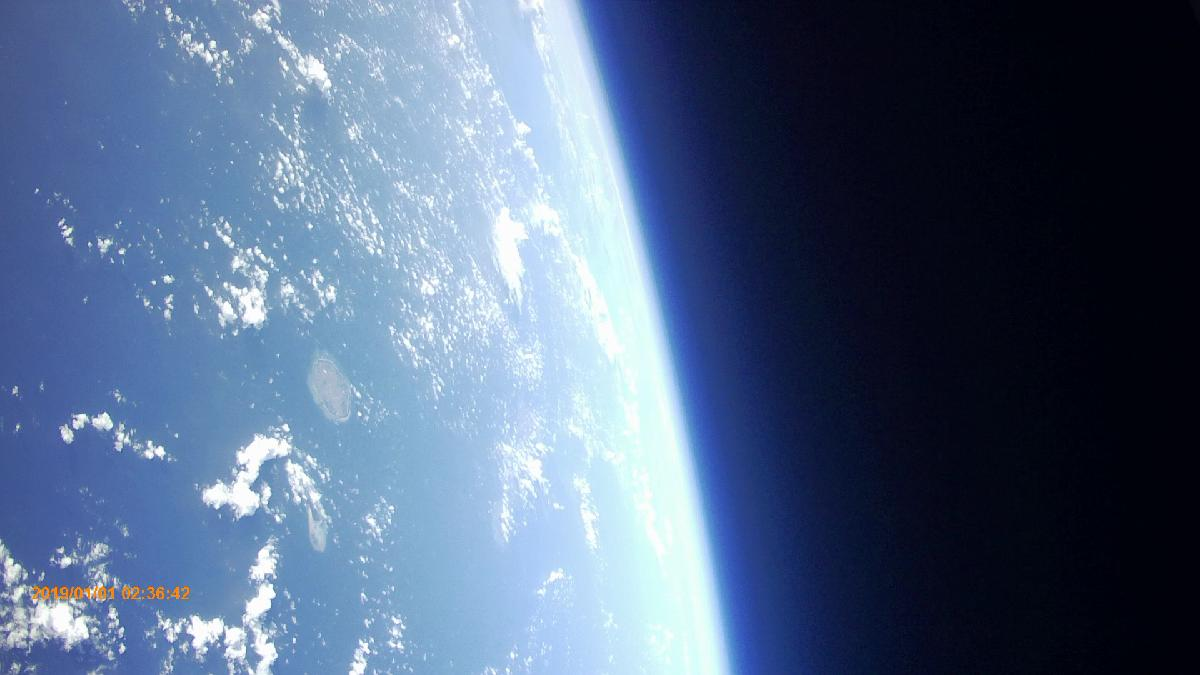

## e-kagakuアカデミー　×　MathWorks®

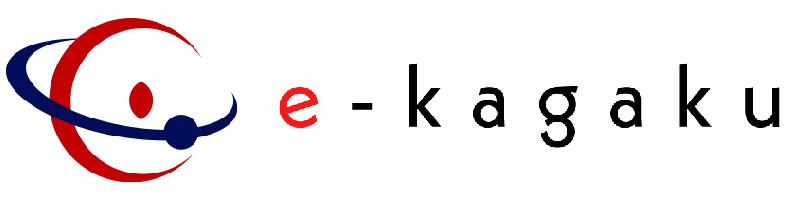　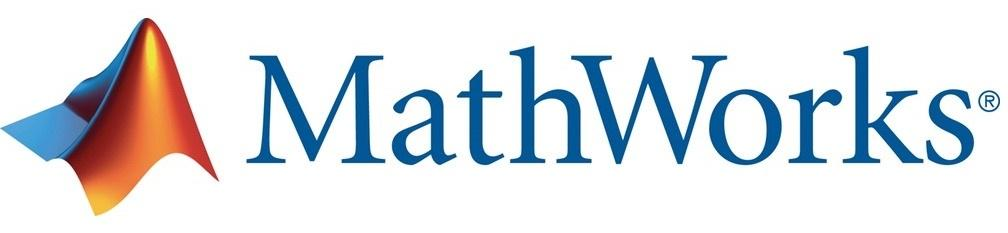

## **Mission3 (Advanced) もっと解析しよう**

宇宙のデータをさらに詳しく解析して研究発表してみましょう．解析の仕方によっては新たな発見をすることができるかもしれません．ここでは，より深くデータについて考察するために必要なスキルを身に着けていきます．

まずは，Mission2 で確認した，高度に対する温度変化について，分析していきます．高度と温度変化データに関する分析方法のイメージがついたら，次は自分で好きなデータについて解析してみましょう！

### データの取り込み

まずは，このセクションを実行し，分析に必要な変数をベースワークスペースに定義しましょう．

load mission3_data.mat

参考までに，上記の処理について説明します．

ここで登場するのは，`load`** 関数**と，"mission3_data.mat" という **MAT-ファイル**です．

**MAT-ファイル**は，ファイルからデータをインポートした変数や，プログラムで作成された変数を保存することができるファイルです．"mission3_data.mat" は，Mission3 で使用する変数を保存しています．

`load`** 関数**は，MAT-ファイルにある変数をインポートする関数です．

インポートが終わると，ワークスペースに，以下 4 つの変数が取り込まれます．これらの変数には，上昇開始から高度 10000m に達するまでのデータを保存しています．

- `t_m3         `: 時刻

- `height_m3    `: 高度

- `temp_m3`             : 気温

- `grad_temp_m3 `: 各時刻における，高度に対する気温変化率

これらの変数は，次以降のセクションで使用します．

### データの可視化と直線近似

まずは，下記のヒントを参考に，高度と気温のデータを散布図でグラフ化してみましょう．さらに近似直線を引いてみましょう．

**ヒント）**[散布図と近似直線](matlab:edit("approximately_straight_line_3.mlx"))

散布図のデータは，近似直線上にありますか？それとも近似直線から少しずれていますか？

### データの相関

上記のグラフは，直線上に分布しているように見えますね．次に，高度データと気温データの相関を調べてみましょう．

**ヒント）**[相関係数](matlab:edit("correlation_coefficient_3.mlx"))

相関係数の値はいくつになりましたか？相関係数の値から，高度と気温の関係性について，どのようなことが言えそうですか？

### 気温の変化率の散布図

次に，気温の変化率について，平均・分散を求めていきます．まずは，データの特徴を見るために，気温の変化率を散布図でグラフ化してみましょう．（縦軸の範囲は -0.05 から 0.05 にすると見やすいです．）



ylim([-5e-2 5e-2]) % 縦軸の範囲は -0.05 から 0.05 に設定

グラフから，少しばらつきがあるのが確認できますね．

今回，高度に対する気温の変化率は予め用意しました．変化率の求め方を知りたい人は，下記 ヒント を見てみましょう．

**ヒント）**[気温の変化率の求め方](matlab:edit("grad_tempreture_vs_height_3.mlx"))

### 平均，分散と標準偏差

それでは，実際に，平均・分散・標準偏差を求めてみましょう．平均・分散を求めることで，新たに分かったこと，またはこれまで解析してきたことを裏付けられますか？

**ヒント）**[平均と分散](matlab:edit("average_variance_3.mlx"))

% 平均


% 分散


% 標準偏差



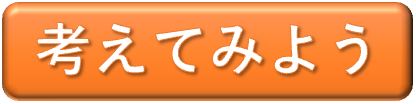

平均値は，先ほど求めた直線近似の結果と比べて，大きいですか？それとも小さいですか？

どうしてそのような結果になったと思いますか？

また，分散や標準偏差の結果から，どのようなことが言えそうですか？

### まとめ

今回，最小二乗法による方法と，隣り合うデータから求めた変化率の平均と，2通りの方法で求めました．

それでは，答え合わせをしましょう！

国際標準大気による定義では，**標高が100メートル上がると気温は 0.649 度下がる**とされています．

計算した結果は，どうでしたか？

私たちも，Mission3 の回答と考察について，[**こちら**](matlab:edit("sbda_mission3_ans.mlx"))にまとめました．

皆さんの考察と同じか，それとも違うものか，ぜひ読んで見てください．

### 別のデータで解析してみよう！

相関・平均・分散の意味を理解したところで，気圧データ(3 列目)や湿度データ(5 列目)についても同様に変化率や平均・分散・相関を求めてみて，得られた結果を元に分析してみましょう．

これでミッションはおわりです．

[**おわりに**](matlab:edit("sbda_mission4final.mlx"))

## **参考**

#### **＊データの配列**

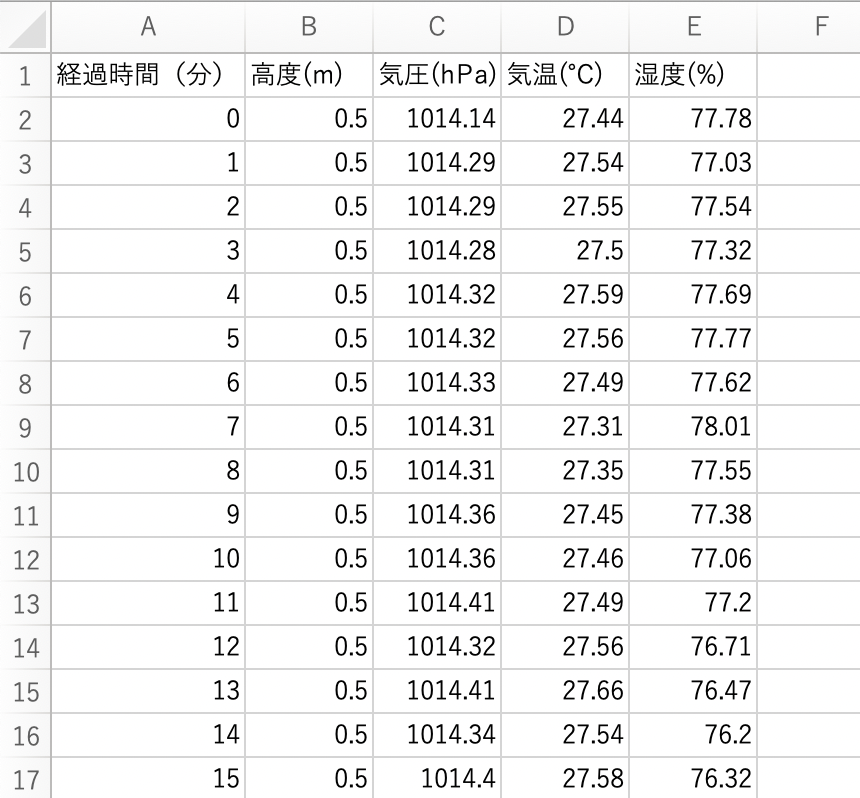

#### **＊**[**大気の特徴**](matlab:edit("atmosphere_3.mlx"))

**＊グラフを描くには？：**[**可視化（グラフ表示）**](matlab:edit("graph_info_3.mlx"))

**＊特定の列のデータを取り出すには？：**[**配列からある範囲を選ぶ**](matlab:edit("array_extract_3.mlx"))

**---------------------------------------**

[Mission2に戻る](matlab:edit("sbda_mission2_0.mlx"))

[Mission1に戻る](matlab:edit("sbda_mission1.mlx"))

Copyright 2020 - 2022 The MathWorks, Inc.